# MTE 546 Data Accquisition Code

University of Waterloo MTE 546 Written by Eugene Li Dec 2019 Updated by Lyndon Tang Jan 2025

close all; clear all; clc;

## Device Configuration

If this is operating correctly the board name should appear

devices = daq.getDevices

devices = ni: National Instruments(TM) NI ELVIS II+ (Device ID: 'Dev1')
   Analog input supports:
      7 ranges supported
      Rates from 0.1 to 1250000.0 scans/sec
      16 channels ('ai0' - 'ai15')
      'Voltage' measurement type
   
   Analog output supports:
      -5.0 to +5.0 Volts,-10 to +10 Volts ranges
      Rates from 0.1 to 2857142.9 scans/sec
      2 channels ('ao0','ao1')
      'Voltage' measurement type
   
   Digital IO supports:
      Rates from 0.1 to 1000000.0 scans/sec
      39 channels ('port0/line0' - 'port2/line6')
      'InputOnly','OutputOnly','Bidirectional' measurement types
   
   Counter input supports:
      Rates from 0.1 to 80000000.0 scans/sec
      2 channels ('ctr0','ctr1')
      'EdgeCount','PulseWidth','Frequency','Position' measurement types
   
   Counter output supports:
      Rates from 0.1 to 80000000.0 scans/sec
      2 channels ('ctr0','ctr1')
      'PulseGeneration' measurement type
   



s = daq.createSession('ni');

% Add analog inputs for each sensor being read
% 'Dev1' corresponds to the ELVIS board
% Each channel 0, 1 corresponds to the analog input on the ELVIS
addAnalogInputChannel(s, 'Dev1', 0, 'Voltage')

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 1
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


addAnalogInputChannel(s, 'Dev1', 1, 'Voltage')

ans =     'Data acquisition session using National Instruments(TM) hardware:
        Will run for 1 second (1000 scans) at 1000 scans/second.
        Number of channels: 2
           index Type Device Channel MeasurementType      Range       Name
           ----- ---- ------ ------- --------------- ---------------- ----
           1     ai   Dev1   ai0     Voltage (Diff)  -10 to +10 Volts
           2     ai   Dev1   ai1     Voltage (Diff)  -10 to +10 Volts
        
     Methods, Events .'


## TODO: Set the sample rate

Set the sample rate by replacing 'nan' with the desired rate in Hz

sample_rate = validate_sample_rate(1000);

Sample rate: 1000.00 Hz


s.Rate = sample_rate;

% Normal Operation
% Read for a set period of time
s.DurationInSeconds = 5;

fprintf("Measurement Started");

Measurement Started

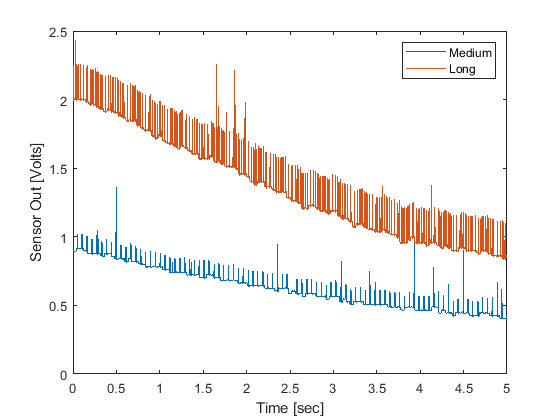

[data, time] = s.startForeground;

figure;
plot(time, data);
xlabel('Time [sec]');
ylabel('Sensor Out [Volts]');
legend('Medium', 'Long');

save("smoothTilted30_70.mat", "data")

## TODO: Save 'data', 'time' to a file

% help save;

## Alternative Read Modes

%{
% Debugging Single-shot Read 
data = s.inputSingleScan;

% Continuous Background Read
figure;
s.DurationInSeconds = 5;
lh = addlistener(s, 'DataAvailable', @(src, event) plot(event.TimeStamps, event.Data));
xlabel('Time [sec]');
ylabel('TODO: Label y-axis [units]');
legend('Medium', 'Long');
s.NotifyWhenDataAvailableExceeds = 8000;
s.startBackground();
s.wait();
delete(lh);
%}


function sample_rate = validate_sample_rate(sample_rate)
assert(isequal(size(sample_rate), size(1)), 'Sample rate must be a scalar');
assert(~isnan(sample_rate), 'Sample rate was not set. Choose a sample rate');
assert((isfloat(sample_rate) && ~isinf(sample_rate)) || isinteger(sample_rate), 'Sample rate must be a number');
assert(sample_rate > 0, 'Sample rate must be positive');
fprintf('Sample rate: %.2f Hz\n', sample_rate);
end